# Results of the Experiement

matlab_data = load('results.mat');
%datadep_data = load('results_datadep.mat')

## The Loop

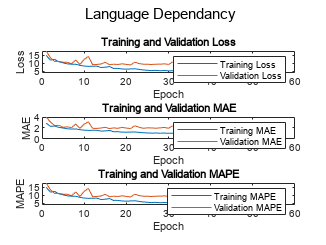

Estonian MAE: 2.9771


Estonian MAPE: 39.5544%


English MAE: 2.4404


English MAPE: 19.5480%


For: estonian

Overall baseline fscore: 100.0004


Overall dsp fscore: 100.0004


For: english

Overall baseline fscore: 50.6886


Overall dsp fscore: 49.2607


% Load the data from the .mat file
load('results.mat');
% Loop over each command
for i = 1:numel(fieldnames(matlab_data))-1
    
    % Extract the command and data for the current iteration
    Field = strcat('Command_',num2str(i+1));
    curr_data = matlab_data.(Field);
    curr_command = curr_data.Call;
    
    % Check if the command is a crossval command
    if strcmp(curr_command(1), 'crossval')
        % Extract the cross validation data
        cross_val_data = curr_data.Languages;
        
        language_names = fieldnames(cross_val_data);

## **Cross validation**

   % Loop over each language and extract the DSP and true F-scores
        for j = 1:length(language_names)
            language = language_names(j);
            dsp_fscore = cross_val_data.(language{1}).DSP_Fscore;
            true_fscore = cross_val_data.(language{1}).True_Fscore;
            fprintf('For: %s', language{1})
            fprintf('Overall baseline fscore: %.4f\n', true_fscore)
            fprintf('Overall dsp fscore: %.4f\n', dsp_fscore)
        end

## **Other commands**

   
    else
    % Extract the weights, history, and predictions data
    history_dict = curr_data.History;
    prediction_data = curr_data.Predictions;
    
    % Plot the history data using the plot_history function
    plot_history(history_dict);
    if strcmp(curr_command(1), 'langdep')
        sgtitle("Language Dependancy ")
    
    elseif strcmp(curr_command(1), 'datadep')
        sgtitle("Data Dependancy " + curr_command(2))
    end
    % Display the MAE and MAPE values
    fprintf('Estonian MAE: %.4f\n', prediction_data.estonian.MAE);
    fprintf('Estonian MAPE: %.4f%%\n', prediction_data.estonian.MAPE);

    fprintf('English MAE: %.4f\n', prediction_data.english.MAE);
    fprintf('English MAPE: %.4f%%\n', prediction_data.english.MAPE);
    
    end
end

% langdep_data = load('results_langdep.mat');

% eval_langdep(langdep_data)